# Actividad 1: Sistema de Primer Orden 

clc
clear

#### Caso I

a=1; b=1;

#### Caso II

% a=10; b=10;

#### Caso III

% a=100; b=100;

Corremos la simulación y tomamos los datos

out = sim('sesion2_act1'); %correr simulación

tf=out.tf;      %salida transfer function.
dif=out.dif;    %salida ec. diferencial

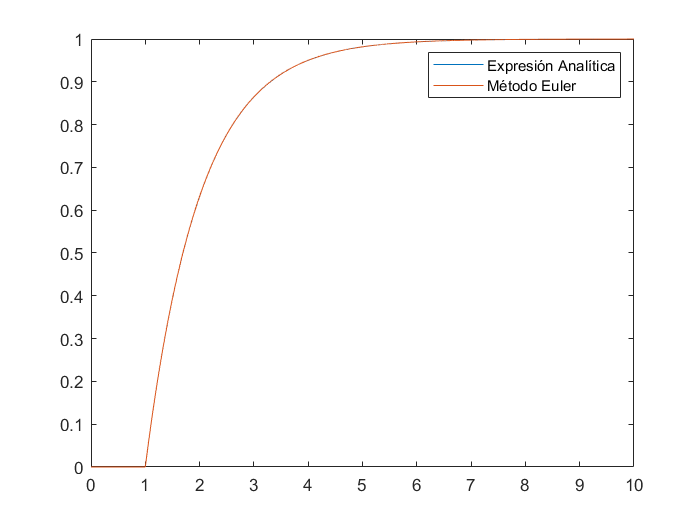

t_len=10; %tiempo de simulación

t = linspace(0, t_len, length(tf));

N=(t_len/0.001)+1;

h=heaviside(t-1);

%plot(t,h)

expr=(b/a)*(h.*(1-exp(-1*a*(t-1))));  %expresión analitica

 plot(t,expr)
 hold on
 plot(t,dif)
 legend('Expresión Analítica','Método Euler')


E=immse(expr, tf.');




# Actividad 2:

## Respuesta Escalón e Impulso

clc
clear
s=tf('s');

a1 = [2*0.7*1, 2*0.3*1, 2*0.7*10, 2*0.3*10, 2*0.7*1];
a0 = [1, 1, 100, 100,1];
b1 = [0, 0, 0, 0, -1];
b0 = [1, 1, 1, 1, 1];

G_c = @(x) (b1(x)*s+b0(x))/(s^2+a1(x)*s+a0(x));
%act 2.2
% subplot(2,1,1)
% hold on
% plot( impulse(G_c(1)))
% plot( impulse(G_c(2)))
% legend('G_c (1)', 'G_c(2)')
% 
% subplot(2,1,2)
% hold on
% plot( impulse(G_c(3)) )
% plot( impulse(G_c(4)) )
% legend('G_c (3)', 'G_c(4)')
datos={}; %Saves the output characteristics, is preallocated for extra speed

for i = [1 : length(a1) ]
    %2.3
    titulo='Respuesta a Escalon para Caso: ' + string(i);
    h(i)=subplot(3,2,i);
    step(G_c(i),10)
    if (i == 5) % Trucazo para poner el último gráfico al medio.
        pos = get(h,'Position');
        new = mean(cellfun(@(v)v(1),pos(1:2)));
        set(h(i),'Position',[new,pos{end}(2:end)])
    end
    title(titulo)
    
   %2.4
    [A,B]=step(G_c(i),10);
    
    P=pole(G_c(i));
    Z=zero(G_c(i));
    Undershoot =min(A); %undershoot
    Tvalle =B(find(A==min(A))); %tiempo de valle
    Overshoot =max(A); %overshoot
    Tmax =B(find(A==max(A))); % tiempo de peak
    Final =A(length(A)); %salida estacionaria.
    
   datosenal= 'Caso: ' + string(i) + '\n'...
    +'Undershoot: ' + string(Undershoot) + '\n'...
    + 'Tiempo de Valle: ' + string(Tvalle) + '\n'...
    + 'Overshoot: ' + string(Overshoot) +'\n'...
    + 'Tiempo de peak: ' + string(Tmax) + '\n'...
    +'Salida estacionaria:' + string(Final) + '\n';

    sprintf(datosenal)
   %2.1

    disp("Polos en: ");
    disp(P);
    disp("Ceros en: ");
    disp(Z);
    
end
%obtener tiempo valle último caso.




## Respuesta en Frecuencia


% t1=linspace(0,30,30001);
% bode(G_c(1));
% 
% %------------------entrada 1
% [A1,B1]=freqresp(G_c(1),3)
% u1abs=abs(A1); u1fase=angle(A1); %
% y_m_1=10*u1abs*sin(3*t1+u1fase); %stationary output of the system
% %------------------entrada 2
% [A2,B2]=freqresp(G_c(1),0);
% u2abs=abs(A2); u2fase=angle(A2);
% y_m_2=10*( u2abs*cos(u2fase)  +  u1abs*sin(3*t1+u1fase));
% %------------------entrada 3
% [A3,B3]=freqresp(G_c(1),10);
% u3abs=abs(A3); u3fase=angle(A3);
% y_m_3=10*u3abs*sin(10*t1+u3fase);
% 
% sys = G_c(1);
% out = sim('sesion2_act2'); %run the simulation
% 
% y1 = out.y1;
% y2 = out.y2;
% y3 = out.y3;
% 
% figure(2)
% subplot(3,1,1)
% plot(t1,y1)
% hold on
% plot(t1,y_m_1)
% legend("y_1 Euler \Delta=10^{-3}", "y_1 ")
% title('Respuesta del sistema con la entrada u_1')
% 
% subplot(3,1,2)
% 
% plot(t1,y2)
% hold on
% plot(t1,y_m_2)
% legend("y_2 Euler \Delta=10^{-3}" , "y_2")
% title('Respuesta del sistema con la entrada u_2')
% 
% 
% subplot(3,1,3)
% 
% plot(t1,y3)
% hold on
% plot(t1,y_m_3)
% legend("y_3 Euler \Delta=10^{-3}", "y_3 ")
% title('Respuesta del sistema con la entrada u_3')